*Copyright 2025 The MathWorks, Inc.*

# **EXERCISE 2 : 5G** **Intercell Interference Modeling**

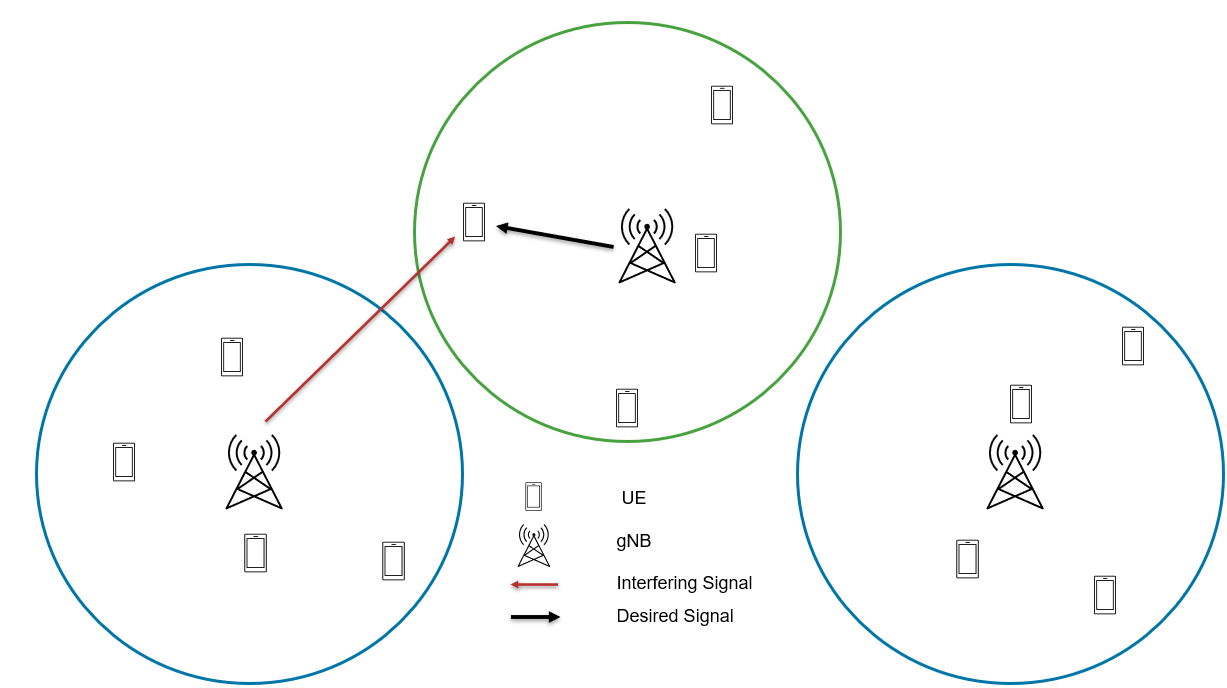

This exercise shows how to simulate a multi cell interference scenario and measure the impact on network performance due to downlink (DL) intercell interference caused by nearby cells. The goals are:

- Model a multi-cell network scenario

- Analyze the impact on user throughput, particularly for users near the cell edge

- Visualize how channel conditions change as a result of inter-cell interference                            

#### Close any previously opened figures and add the path to the helpers and utilities directories 

- Close all previous windows

- Add path to helpers and utilities

- Reset the random number generator for reproducibility

all_figs = findall(0, 'type', 'figure');close(all_figs); 
p = addpath(fullfile('.', 'Shared', 'Helpers'), fullfile('.', 'Shared', 'Utilities')); 
rng("default")   

#### Initialize Variables and Wireless Network Simulator

- Number of UEs per cell and cell of interest 

- Set Radius of each cell (in meters)

- Initialize the Wireless Network Simulator

- Number of frames to simulate and simulation time in seconds 

- Launch the wireless network viewer to visualize the network during simulation

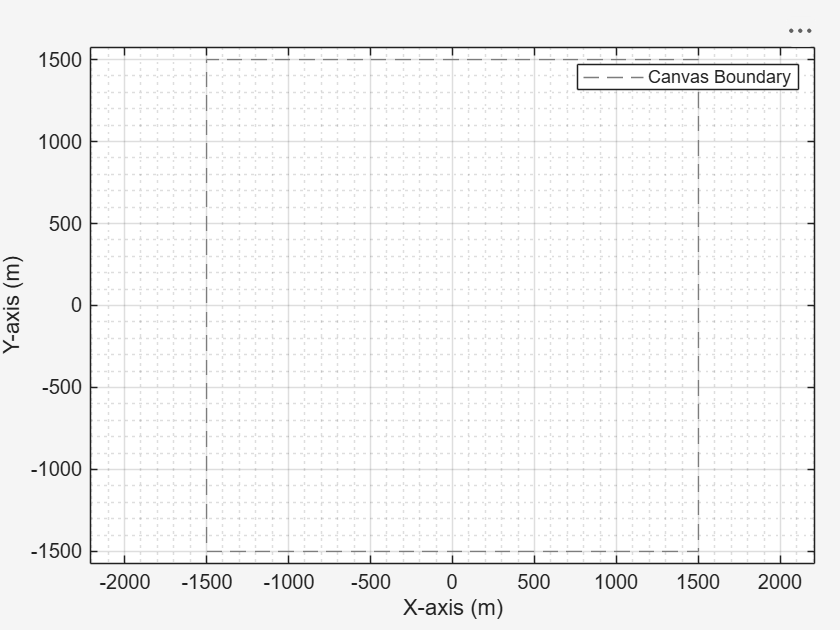

numUEsPerCell = 4;
cellofInterest = 3;
cellRadius = 500;
numFrameSimulation = 10;
simulationTime = numFrameSimulation*1e-2;
networkSimulator = wirelessNetworkSimulator.init;
viewerObj = wirelessNetworkViewer(CanvasSize=[3000 3000]);

# Task 1/8: Create three 5G base stations 

**Instructions to complete the task**

Use` nrGNB() `function to create a NR base station 

Store NR base station in a variable named "gNB"

Hint:type `doc nrGBN`  in command window and see the "Syntax" section.

Note : use the following values as arguments 

- "Name",gNBNames

- "Position",gNBPositions

- "CarrierFrequency",carrierFrequency

numCells = 3;
gNBPositions = [0 0 30; 750 433 30; 750 -433 30];
gNBNames = ["gnb-1","gnb-2","gnb-3"];
carrierFrequency = 2.6e9;

% <Enter your code below>
gNBs = nrGNB("CarrierFrequency",carrierFrequency, ...
        "Name",gNBNames, ...
        "Position",gNBPositions);

#### Visualize the 5G base stations in the Network Viewer and add them as nodes to the network simulator

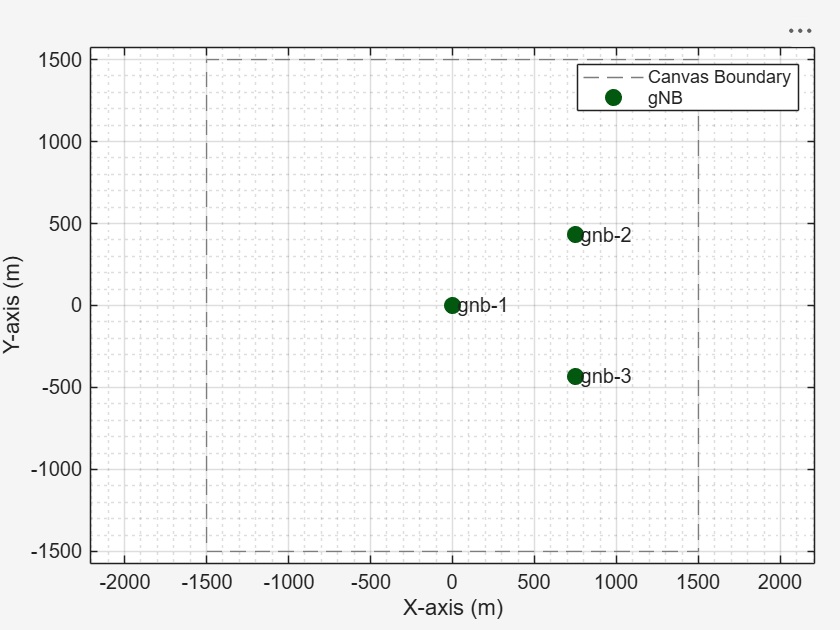

addNodes(networkSimulator,gNBs);
addNodes(viewerObj,gNBs,Type="gNB");

# Task 2/8: Create NR user equipments for first cell

**Instructions to complete the task**

Use `nrUE()` function to create a 5G user equipment (UE) 

Store NR base station in a variable named "UE"

Hint: type `doc nrUE` in command line, and see the "Syntax" section.

Note : use the following values as arguments 

- "Position",uePositions, ...

-  "Name",ueNames

uePositions = generateUEPositions(cellRadius,gNBPositions(1,:),numUEsPerCell);
ueNames = "ue-" + (1:size(uePositions,1));

% <Enter your code below>
UEs =  nrUE("Position",uePositions, ...
    "Name",ueNames);

# Task 3/8: Create the first cell in the 5G network.

**Description of the task**

Connect UE(s) to the gNB and full buffer downlink traffic 

A note on full-buffer traffic

- Transmitter always has data to send (buffer never empty) 

- MAC queue is always full 

- Performance depends on network capacity 

- Used to measure maximum throughput 

- Helps study interference and scheduling 

- Common in 5G and WLAN simulations

**Instructions to complete the task**

Use connectUE() function to connect gNB to corresponding UEs

Hint: type `doc connectUE`, and see the "Syntax" section.

Note : use the following values as arguments 

- gNBs(1)

- UEs

- FullBufferTraffic="DL"

% <Enter your code below>
connectUE(gNBs(1),UEs,FullBufferTraffic="DL");

**Visualize the first cell in the Network Viewer and add UEs to the network simulator**

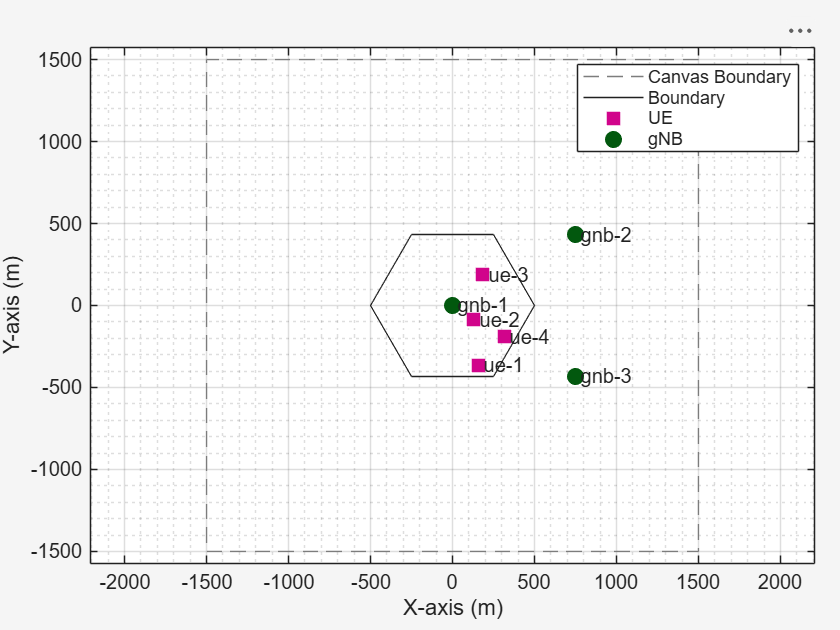

addNodes(networkSimulator,UEs)
addNodes(viewerObj,UEs,Type="UE");
showBoundary(viewerObj,Position=gNBPositions(1,:), BoundaryShape="Hexagon",Bounds=cellRadius, Name="Cell-1")

# Task 4/8: Create  NR user equipments for second cell

**Instructions to complete the task**

Use `nrUE()` function to create a 5G user equipment (UE) 

Store NR base station in a variable named "UE"

Hint: type `doc nrUE` in command line, and see the "Syntax" section.

Note : use the following values as arguments 

- "Position",uePositions

-  "Name",ueNames

uePositions = generateUEPositions(cellRadius,gNBPositions(2,:),numUEsPerCell);
ueNames = "ue-" + (1:size(uePositions,1));

% <Enter your code below>
UEs =  nrUE("Position",uePositions, ...
    "Name",ueNames);

# Task 5/8: Create the second cell in the 5G network.

**Instructions to complete the task**

Use connectUE() function to connect gNB to corresponding UEs

Hint: type `doc connectUE`, and see the "Syntax" section.

Note : use the following values as arguments 

- gNBs(2)

- UEs

- FullBufferTraffic="DL"

% <Enter your code below>
connectUE(gNBs(2),UEs,FullBufferTraffic="DL");

**Visualize the 2nd cell in the Network Viewer and add UEs to the network simulator**

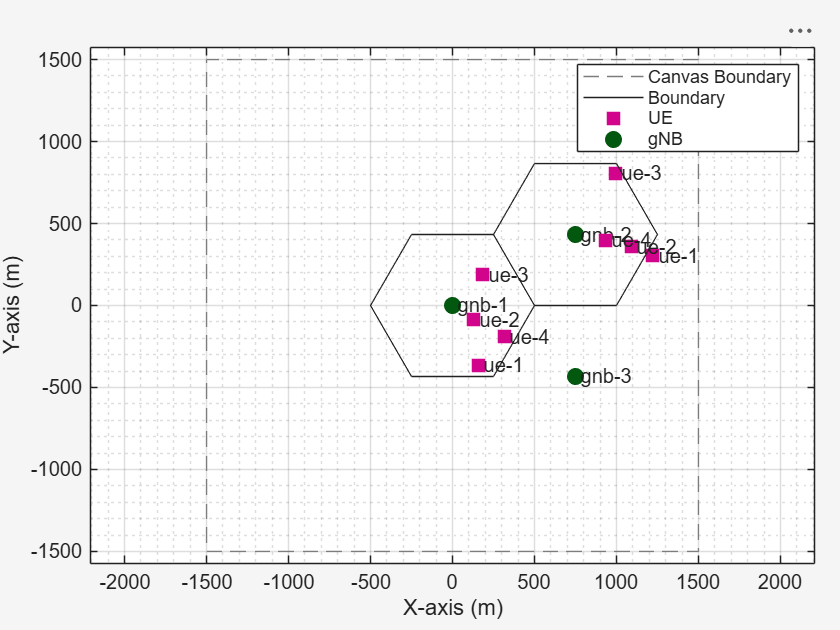

addNodes(networkSimulator,UEs)
addNodes(viewerObj,UEs,Type="UE");
showBoundary(viewerObj,Position=gNBPositions(2,:), BoundaryShape="Hexagon",Bounds=cellRadius, Name="Cell-2")

# Task 6/8: Create  NR user equipments for third cell

**Instructions to complete the task**

Use `nrUE()` function to create a 5G user equipment (UE) 

Store NR base station in a variable named "UE"

Hint: type `doc nrUE` in command line, and see the "Syntax" section.

Note : use the following values as arguments 

- "Position",uePositions

-  "Name",ueNames

**Position the UEs within the cell of interest**

You can choose any of the three cells as the cell of interest for interference analysis. In this case, we select Cell 3.

Select random position of UEs in cell three 

uePositions = generateUEPositions(cellRadius,gNBPositions(cellofInterest,:),numUEsPerCell);

Place UEs in particular region cell-3  

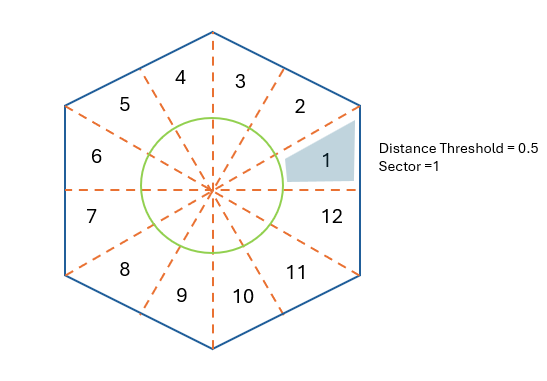

controlUEPositions = false;
if controlUEPositions
    distanceThreshold = 0.8; % fraction of cell radius
    sector =  5; % 1 to 8, represents a sector of 45 degrees
    uePositions = generateUEPositions(cellRadius,gNBPositions(cellofInterest,:),numUEsPerCell,distanceThreshold,sector);
end

Generate the UE names for Cell 3

ueNames = "ue-" + (1:size(uePositions,1));

% <Enter your code below>
UEs = nrUE(Name=ueNames,Position=uePositions);

# Task 7/8: Create the third cell in the 5G network

**Instructions to complete the task**

Use connectUE() function to connect gNB to corresponding UEs

Hint: type `doc connectUE`, and see the "Syntax" section.

Note : use the following values as arguments 

- gNBs(cellofInterest)

- UEs

- FullBufferTraffic="DL"

% <Enter your code below>
connectUE(gNBs(cellofInterest),UEs,FullBufferTraffic="DL");

**Visualize the 3rd cell in the Network Viewer and add UEs to the network simulator**

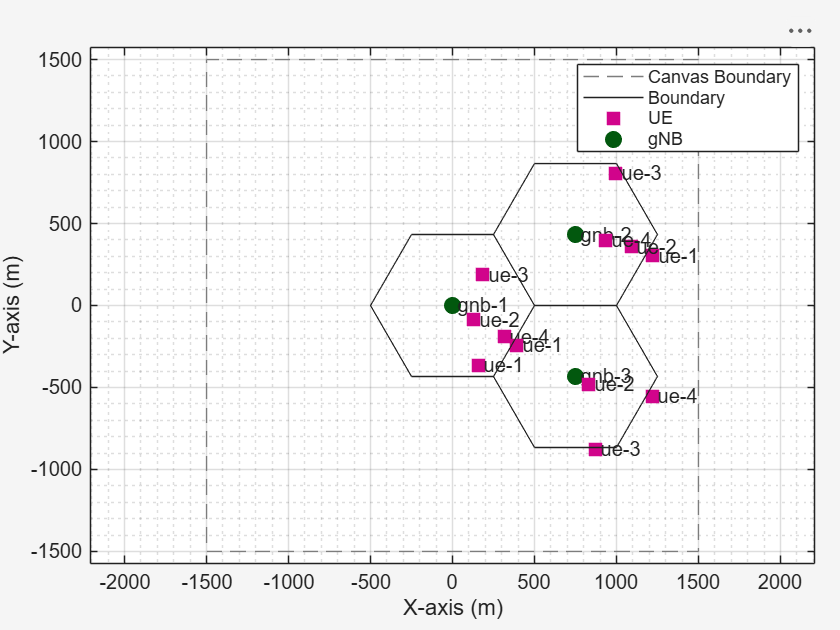

addNodes(networkSimulator,UEs)
addNodes(viewerObj,UEs,Type="UE");
showBoundary(viewerObj,Position=gNBPositions(3,:), BoundaryShape="Hexagon",Bounds=cellRadius, Name="Cell-3")

#### Add channel Model 

- The default channel model is Free Space Path Loss (FSPL).

- You can use prebuilt channel models for various deployment scenarios defined in 3GPP TR 38.901.

- Control whether small-scale fading is applied to interfering signals in the channel model.

- You also use custom channel models 

fspl = true;
if ~fspl
channel = h38901Channel(Scenario="UMa");
addChannelModel(networkSimulator,@channel.channelFunction);
connectNodes(channel,networkSimulator,InterfererHasSmallScale=true);
end

#### Enable visualizations

The displayed visualizations and metrics correspond to the selected cell of interest.

- Cell Performance Metrics – Shows key KPIs like throughput, fairness, and buffer status 

- RLC Metrics – Displays data transmitted at the RLC layer for each UE 

- BLER Metrics – Visualizes block error rates in uplink and downlink 

- Resource Grid Allocation – Shows time-frequency resource allocation and HARQ activity 

- Channel Quality – Displays MCS variations across time and frequency 

- Simulation Summary – Compares achieved performance with theoretical limits

simSchedulingLogger = helperNRSchedulingLogger(numFrameSimulation, gNBs(cellofInterest),UEs,LinkDirection="DL");

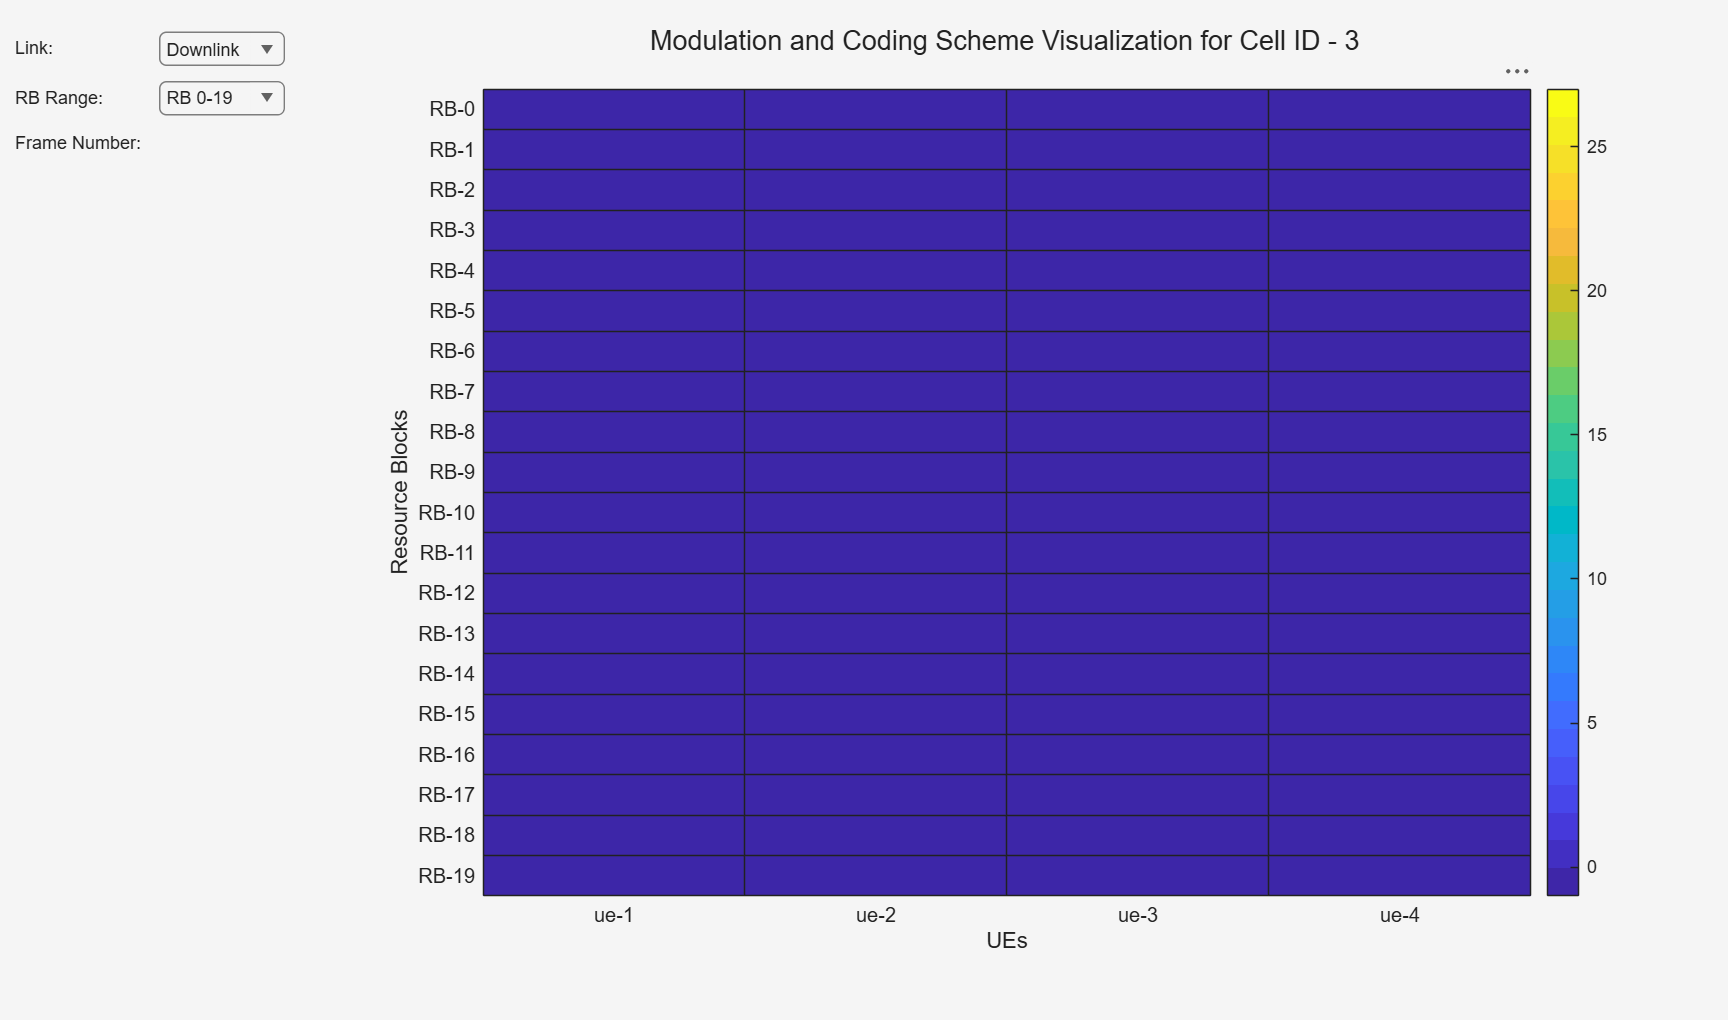

gridVisualizer = helperNRGridVisualizer(numFrameSimulation,gNBs(cellofInterest),UEs, ResourceGridVisualization=false,SchedulingLogger= simSchedulingLogger,MCSGridVisualization=true,CellOfInterest=cellofInterest);

metricsVisualizer = helperNRMetricsVisualizer(gNBs(cellofInterest),UEs,CellOfInterest=cellofInterest,RefreshRate=100,PlotSchedulerMetrics=true,PlotPhyMetrics=false,LinkDirection="DL");

# Task8/8: Run the Simulation 

Runs the discrete-event simulator in MATLAB to execute the network model.

**Instructions to complete the task**

Use run() function to run the model    

Type `doc wirelessnetworksimulator.run` in the MATLAB Command Window, and see the "Syntax" section.

Note : use the following values as arguments 

- networkSimulator

- simulationTime

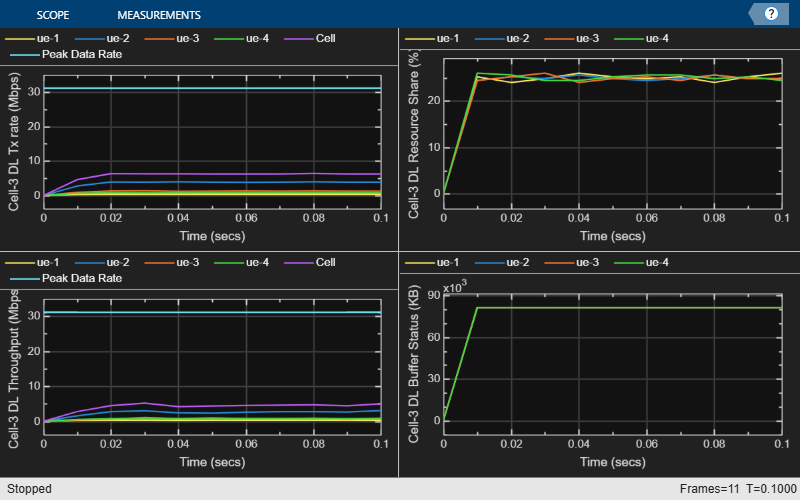

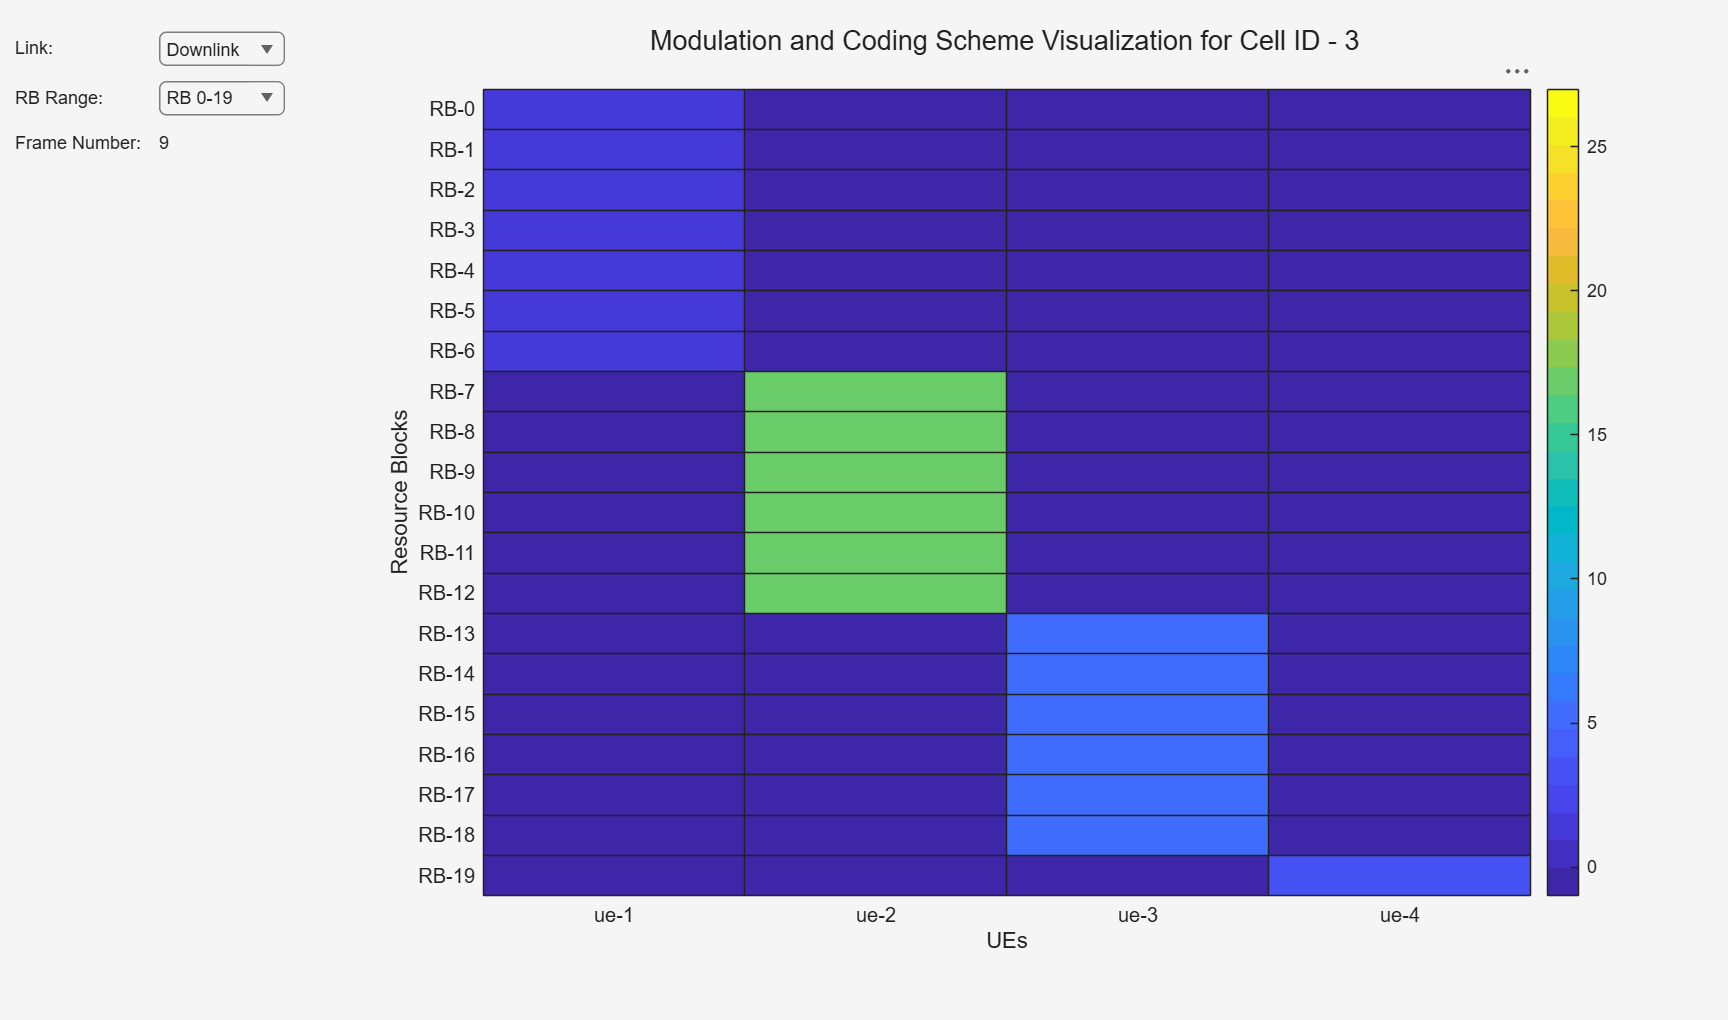

% <enter code below>
run(networkSimulator, simulationTime);

displayPerformanceIndicators(metricsVisualizer)

Peak DL throughput: 31.11 Mbps
Achieved cell DL throughput: 4.42 Mbps
Achieved DL throughput for each UE: [0.31        2.59        0.78        0.74]
Peak DL spectral efficiency: 6.22 bits/s/Hz
Achieved DL spectral efficiency for cell: 0.88 bits/s/Hz
Block error rate for each UE in the DL direction: [0.051       0.293       0.354           0]



path(p);

*Copyright 2025-2026 The MathWorks, Inc.*